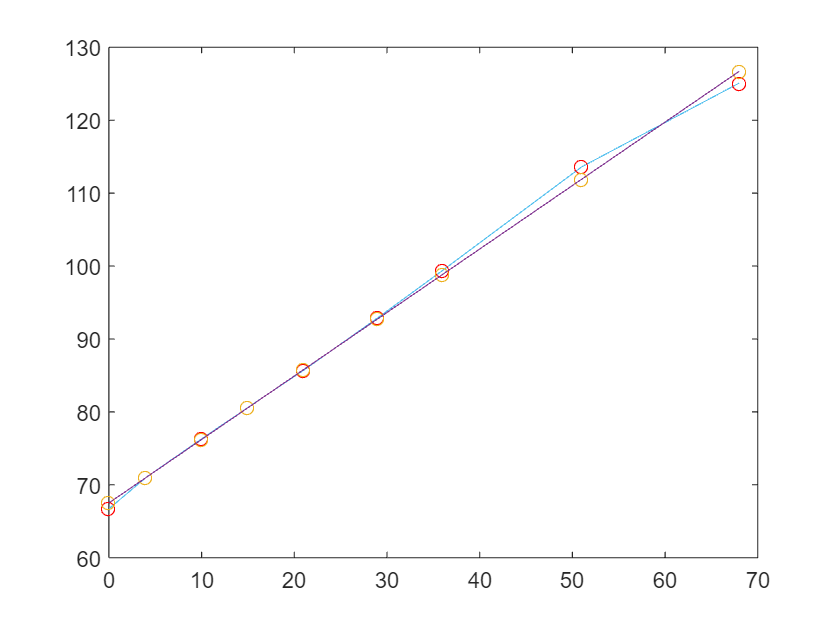

Dados la matriz A:


A_ =      0     1
     4     1
    10     1
    15     1
    21     1
    29     1
    36     1
    51     1
    68     1


y el vector de observaciones:


ans =    66.7000
   71.0000
   76.3000
   80.6000
   85.7000
   92.9000
   99.4000
  113.6000
  125.1000


se tiene:
******************************


m = 9

n = 2

rango = 2

N =        10144         234
         234           9


x =     0.8706
   67.5078


y_gorro =    67.5078
   70.9904
   76.2142
   80.5674
   85.7912
   92.7564
   98.8508
  111.9105
  126.7113


v_gorro =     0.8078
   -0.0096
   -0.0858
   -0.0326
    0.0912
   -0.1436
   -0.5492
   -1.6895
    1.6113


clear all
hold off
A =  [2; 2; 1; 2*pi]
At = transpose(A);
yt = [4.20 4.10 1.98 12.5]
y = transpose(yt) ;
t =  ;
inv(At*A)*At*y;

mmcc(A, yt, t);

function x = mmcc(A_, yt_, t_)
    disp("")
    disp("Dados la matriz A:")
    A_
    disp("y el vector de observaciones:")
    transpose(yt_)
    disp("se tiene:")
    disp("******************************")
    [m,n] = size(A_)
    rango = rank(A_)
    N = transpose(A_)*A_
    x = inv(N)*transpose(A_)*transpose(yt_)
    y_gorro = A_*x
    v_gorro = y_gorro - transpose(yt_)
    hold on
    plot(t_, transpose(yt_), "ro")
    plot(t_, y_gorro, "o")
    plot(t_, x(1)*t_ + x(2), "-")
    %plot(t, x(1)*t_+ x(2),".")
end